## Quadrotor Formations Coordination Simulator

This is the main file that one needs to execute to generate the results that we show in our paper.

clear all
close all
clc
load handel

% For different number of total quadrotors, we may need to change the lower
% bound of the con0 in quadrotor class for decentralization (0.001/0.0001)
rng(7)

% Some definitions
R2D = 180/pi;
D2R = pi/180;

e1 = [1 0 0]';
e2 = [0 1 0]';
e3 = [0 0 1]';

R0 = eye(3);

Creation of the network of platoons

%% Network setup
network_index = 0;                          % network Index
numOfFormations = 1;                        % num of formations
numOfQuadrotors = [8]; %[4,5,6,7,8,10];    % num of quadrotors in each formation, for N=8, 10, the lower bound of the con0 is set as 0.001
totalNumOfQuadrotors = sum(numOfQuadrotors);


%% Initial setup
quadrotorSeperationMean = 2;
quadrotorSeperationVar = 1; 
formationSeperationMean = 3;
formationSeperationVar = 2;

%% Define the initial quadrotor position/translational velocity/attitude (Eular)/angular velocity 
quadrotorPosition = [0, 0, -5]';                % Zeroth quadrotor position
quadrotorTransVelocity = [0, 0, 0]';            % Zeroth quadrotor velocity
quadrotorAttitude = R0;                         % Zeroth quadrotor attitude
quadrotorAngVelocity = [0, 0, 0]';              % Zeroth quadrotor angular velocity

state_ki = [quadrotorPosition; quadrotorTransVelocity; quadrotorAttitude(:,1); quadrotorAttitude(:,2); quadrotorAttitude(:,3); quadrotorAngVelocity];

% Set the desired geometric configuration
desiredSeparation_ki = 0;              % Desired separation from the leader

%% Define the initial states and desired states for all the quadrotors
for k = 1:1:numOfFormations           % for every formation k
    
    parameters_k = [];
    noiseMean_k = [];
    noiseStd_k = [];
    states_k =  [];                   % initial states collection
    desiredSeperation_k = [];

    % varepsilon = [0.1, 0.1 ,0.1, 0.1, 0.2-0.02*4, 0.2-0.02*5];  % 0.2-0.01*i

    for i = 1:1:numOfQuadrotors(k)    % for every quadrotor in the k-th formation

        % Quadrotor parameters (assumed heterogenuous)
        mass_ki = (0.55-0.1*0.55) + ((0.55+0.1*0.55)-(0.55-0.1*0.55))*rand(1);                 % 10% uncertainties r=a+(b-a).*rand(N,1)
        armlength_ki = (0.265-0.01*0.265) + ((0.265+0.01*0.265)-(0.265-0.01*0.265))*rand(1);   % 0.01 uncertainties
        J_xx_ki = (0.0022-0.01*0.0022) + ((0.0022+0.01*0.0022)-(0.0022-0.01*0.0022))*rand(1);  % 0.01 uncertainties
        J_yy_ki = (0.0029-0.01*0.0029) + ((0.0029+0.01*0.0029)-(0.0029-0.01*0.0029))*rand(1);  % 0.01 uncertainties
        J_zz_ki = (0.0053-0.01*0.0053) + ((0.0053+0.01*0.0053)-(0.0053-0.01*0.0053))*rand(1);  % 0.01 uncertainties
        % J_xx_ki = 10; %(10-0.01*0.0022) + ((0.0022+0.01*0.0022)-(0.0022-0.01*0.0022))*rand(1);  % 0.01 uncertainties
        % J_yy_ki = 10; %(10-0.01*0.0029) + ((0.0029+0.01*0.0029)-(0.0029-0.01*0.0029))*rand(1);  % 0.01 uncertainties
        % J_zz_ki = 10; %(0.0053-0.01*0.0053) + ((0.0053+0.01*0.0053)-(0.0053-0.01*0.0053))*rand(1);  % 0.01 uncertainties
        g = 9.81;  % gravitational acceleration
        varepsilon_i = 0.1; % varepsilon(i); % 0.2-0.02*i; 

        % Collection of the initial/initially desired states of each quadrotor
        states_k = [states_k, state_ki];
        
        % Define quadrotor's initial positions/velocities/accelerations
        quadrotorPosition = quadrotorPosition - (quadrotorSeperationMean + quadrotorSeperationVar*(rand(1)-0.5)) * e1;
        quadrotorTransVelocity = [0, 0, 0]';
        quadrotorAttitude = R0; 
        quadrotorAngVelocity = [0, 0, 0]';
        state_ki = [quadrotorPosition; quadrotorTransVelocity; quadrotorAttitude(:,1); quadrotorAttitude(:,2); quadrotorAttitude(:,3); quadrotorAngVelocity];
        
        % Desired quadrotor positions 
        desiredSeperation_k = [desiredSeperation_k, desiredSeparation_ki];
        desiredSeparation_ki = desiredSeparation_ki + quadrotorSeperationMean;

        % Collection of quadrotor parameters
        quadrotorParameters_i = [mass_ki; armlength_ki; J_xx_ki; J_yy_ki; J_zz_ki; g; varepsilon_i];
        parameters_k = [parameters_k, quadrotorParameters_i];

        % Noise parameters (zero mean, uniform distributed variance)
        noisemean_ki = zeros(3,1); % rand(3,1) - 0.5 * ones(3,1);
        noisestd_ki = 0.01 * rand(3,1);

        noiseMean_k = [noiseMean_k, noisemean_ki];
        noiseStd_k = [noiseStd_k, noisestd_ki];
            
    end
    
    % Computation of the first vehicle's position of the next formation
    quadrotorPosition = states_k(1:3,end) - (formationSeperationMean + formationSeperationVar*(rand(1)-0.5)) * e1;
    
    % Collection of states for the next formation
    state_ki = [quadrotorPosition; quadrotorTransVelocity; quadrotorAttitude(:,1); quadrotorAttitude(:,2); quadrotorAttitude(:,3); quadrotorAngVelocity];
    desiredSeparation_ki = 0;

    parameters{k} = parameters_k;   % 7 parameters in total
    states{k} = states_k;
    desiredSeparation{k} = desiredSeperation_k;
    noiseMean{k} = noiseMean_k;
    noiseStd{k} = noiseStd_k;
    
end

net = Network(network_index,numOfFormations,numOfQuadrotors,parameters,states,desiredSeparation,noiseMean,noiseStd);

Plotting the network of platoons

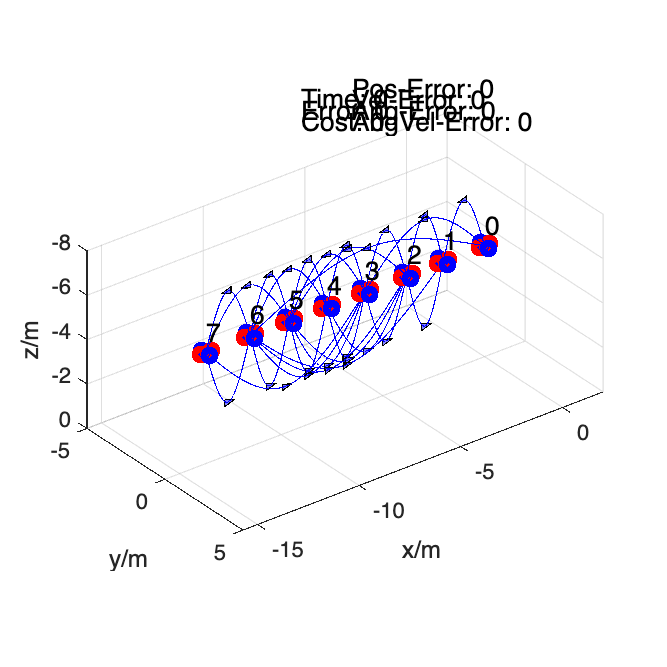

% Visual setup
fig1 = figure('pos',[0 200 800 800]);
h = gca;      % gca = get current axis handle
view(3);
fig1.CurrentAxes.ZDir = 'Reverse';
fig1.CurrentAxes.YDir = 'Reverse';

axis equal;
grid on;

xlabel('x/m');
ylabel('y/m');
zlabel('z/m');

% xlim([-10 2]);
% ylim([-5 5]);
% zlim([-8 0]);

% Plot the initial network to test the codes
hold(h, 'on');
net.drawNetwork(1)

Running the Simulation - Updating the states

% % Use the visual setup we have tested above
% fig2 = figure('pos',[0 200 800 800]);
% h = gca;      % gca = get current axis handle
% view(3);
% fig2.CurrentAxes.ZDir = 'Reverse';
% fig2.CurrentAxes.YDir = 'Reverse';
% 
% axis equal;
% grid on;
% 
% xlabel('x/m');
% ylabel('y/m');
% zlabel('z/m');
% 
% xlim([-10 2]);
% ylim([-5 5]);
% zlim([-8 0]);
% 
% % Draw the initial network in another figure
% hold(h, 'on');
% net.drawNetwork(2)

%%% Global controller synthesis specifications
% Error dynamics I/II, centralized/decentralized, stabilizing/robust, and upperBound on \gamma^2
errorDynamicsType = 2;  % Error dynamics formulation I or II
isCentralized = 0;      % Centralized or decentralized controller synthesis
issMS = 1;               % Involve sMS constraints (1) or not (0)
isOnlyStabilizing = 0;  % Stabilizing controller or Disturbance robust Controller)
gammaSqBar = 10;        % For the constraint: gamma^2 <= gammaSqBar % Desired max noise attenuation

%%% Local passivating controller synthesis specifications 
% LowerBound on \nu and upperBound on \rho 
nuBar = -40;       % For the constraint: nuBar <= nu     -40,-20
rhoBar = 15;       % For the constraint: rhoHat <= rho <= rhoBar  15,20

%%% Parameterized approach to co-design
%% Optimizing gammaSq with respect to the co-design parameters
% pVals = net.optimizeCodesignParameters(isCentralized,issMS)
% pVals = [0.1731 0.1565 0.1579 0.1726 0.1693];
% pVals = [0.1499 0.1476 0.1499 0.1503 0.1500 0.1499];
pVals = [0.1511 0.1497 0.1477 0.1455 0.1497 0.1490 0.1498];
% pVals = ones(1,numOfQuadrotors(1)-1);
% for i = 1:1:numOfQuadrotors(1)-1
%     pVals(i) = 0.5 - 0.055*i;
% end
% pVals = 0.15*ones(numOfQuadrotors(1)-1); 

tic
net.loadFormationControllers(errorDynamicsType,isCentralized,issMS,isOnlyStabilizing,gammaSqBar,nuBar,rhoBar,pVals);

Data saved at: 1.
LMI is feasible at: 1, thus continued.
Current K at i = 1
   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000
   -0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000
    0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000
   -0.0000    0.0000    0.0000   -0.0437    0.0000    0.0000
   -0.0000   -0.0000   -0.0000    0.0000   -0.0437   -0.0000
    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0437

Data saved at: 2 after 1.
LMI is feasible at: 2 after 1.
 Local controller updated at j = 1
Current K at i = 2
   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
    0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0000    0.0000    0.0000   -0.0437    0.0000    0.0000    0.0000    0.0000   

toc

Elapsed time is 7.103698 seconds.



%%% To check compositionality, lets see K_{13} value at decentralized iteration = 3,4,5 and 6
% format long
% net.formations(1).KSequence{3}{1,3}
% net.formations(1).KSequence{4}{1,3}
% net.formations(1).KSequence{5}{1,3}
% net.formations(1).KSequence{6}{1,3}

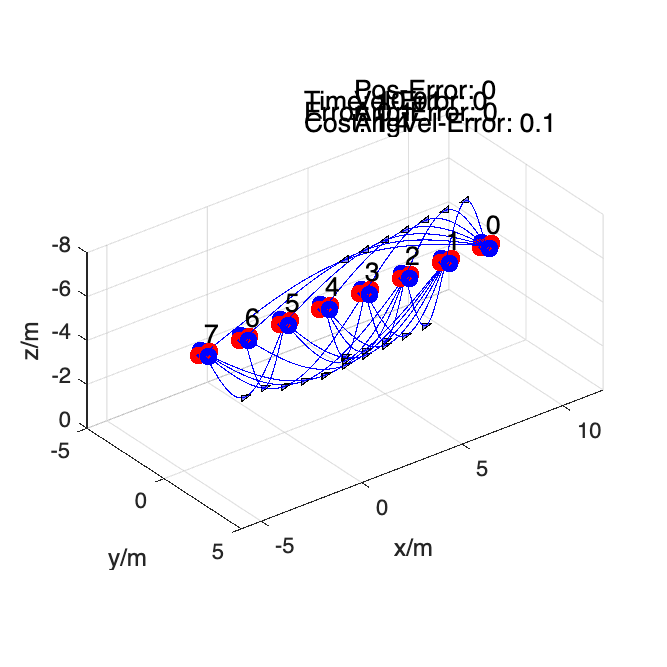

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Set up the simulation parameters
dt = 0.01;
tMax = 10; 
tArray = 0 : dt : tMax;
timeLength = length(tArray);

% Quadrotor platoon leader's trajectory specification
tVals = tMax*[0, 0.5, 1];     % Special time instants (inbetween which the acceleration is constant)
% vxVals = [1 0 0];  % x-velocities to be achived at these time instants
% vyVals = [0 1 1];  % y-velocities to be achived at these time instants

vxVals = 2*[0.5 0.5 0.5];
vyVals = [0 0 0];

% Generate the leader's state profile for straight line trajectory
net.generateLeadersControlProfiles(tVals, vxVals, vyVals);


% Update the formations in real time and generate the animation of the motion
for t = tArray

    % % Use this update function to achieve the update of the entire network
    % % Update sequence: errors ---> control inputs ---> states
    % %                     ^                               |
    % %                     |_______________________________| 
    % Use this to check if the quadrotors crashed the ground
    % for k = 1:1:numOfFormations
    %     for i = 1:1:numOfQuadrotors(k)
    %         if (net.formations(k).quadrotors.states(3,i) >= 0)
    %             h = msgbox('Crashed!!!', 'Error','error');
    %             break;
    %         end
    %     end
    % end
    net.update(t, dt, tMax);

    % Redraw the network to generate the animation
    net.redrawNetwork(1)
    pause(0.01)

end


% Let's listen to a song and cheers for finishing the code running!
% sound(y,Fs)

Figure plotting

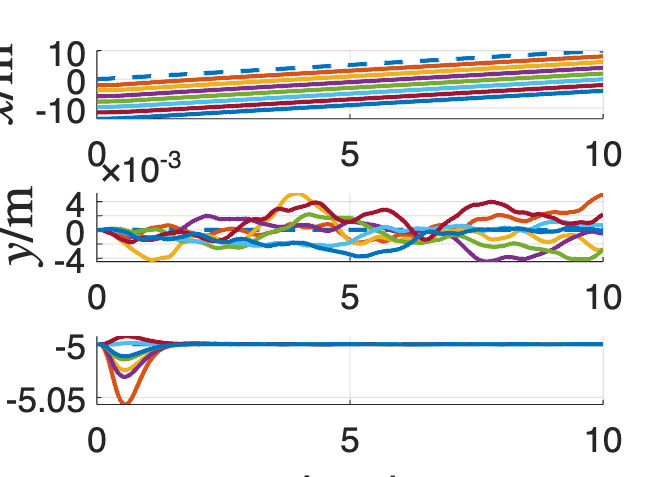

% Plot the states/errors history
close all
C = linspecer(numOfQuadrotors(1));


% Figure 1: real time position tracking histories 
figure('Position',[0 510 510 365]);
axes('NextPlot','replacechildren', 'ColorOrder',C);
subplot(3,1,1)
hold on
plot(tArray,net.formations(k).quadrotors(1).leaderStateHistory(:,1)','--',LineWidth=2);
for k = 1:1:numOfFormations
    for i = 2:1:numOfQuadrotors(k)
        plot(tArray,net.formations(k).quadrotors(i).followerStateHistory(:,1)','-',LineWidth=2);
    end
end
set(gca,fontsize=16);
ylabel('$x$/m','Interpreter','latex',fontsize=24)
grid on

subplot(3,1,2)
hold on
plot(tArray,net.formations(k).quadrotors(1).leaderStateHistory(:,2)','--',LineWidth=2);
for k = 1:1:numOfFormations
    for i = 2:1:numOfQuadrotors(k)
        plot(tArray,net.formations(k).quadrotors(i).followerStateHistory(:,2)','-',LineWidth=2);
    end
end
set(gca,fontsize=16);
ylabel('$y$/m','Interpreter','latex',fontsize=24)
grid on

subplot(3,1,3)
hold on
plot(tArray,net.formations(k).quadrotors(1).leaderStateHistory(:,3)','--',LineWidth=2);
for k = 1:1:numOfFormations
    for i = 2:1:numOfQuadrotors(k)
        plot(tArray,net.formations(k).quadrotors(i).followerStateHistory(:,3)','-',LineWidth=2);
    end
end
set(gca,fontsize=16);
ylabel('$z$/m','Interpreter','latex',fontsize=24)
xlabel('time/s','Interpreter','latex',fontsize=24)
% xlim([0 10]);
% ylim([-80 300]);
grid on 

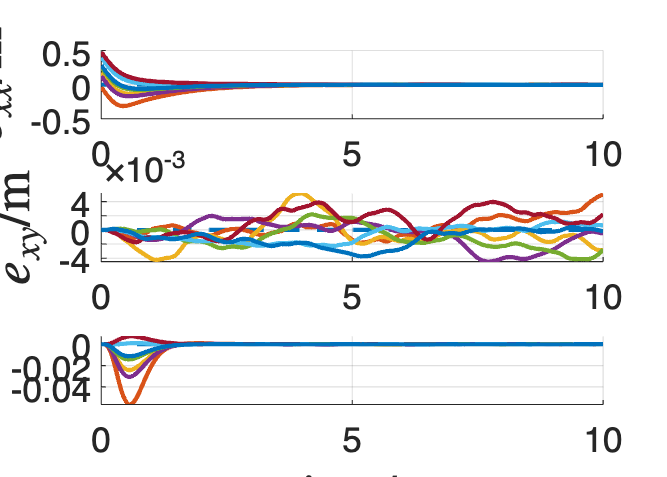



% Figure 2: real time position tracking errors histories
figure('Position',[510 510 510 365]);
axes('NextPlot','replacechildren', 'ColorOrder',C);
subplot(3,1,1)
hold on
plot(tArray,zeros(1,timeLength),'--',LineWidth=2);
for k = 1:1:numOfFormations
    for i = 2:1:numOfQuadrotors(k)
        plot(tArray,net.formations(k).quadrotors(i).errorHistory(:,1)','-',LineWidth=2);
    end
end
set(gca,fontsize=16);
ylabel('$e_{xx}$/m','Interpreter','latex',fontsize=24)
grid on 

subplot(3,1,2)
hold on
plot(tArray,zeros(1,timeLength),'--',LineWidth=2);
for k = 1:1:numOfFormations
    for i = 2:1:numOfQuadrotors(k)
        plot(tArray,net.formations(k).quadrotors(i).errorHistory(:,2)','-',LineWidth=2);
    end
end
set(gca,fontsize=16);
ylabel('$e_{xy}$/m','Interpreter','latex',fontsize=24)
grid on 

subplot(3,1,3)
hold on
plot(tArray,zeros(1,timeLength),'--',LineWidth=2);
for k = 1:1:numOfFormations
    for i = 2:1:numOfQuadrotors(k)
        plot(tArray,net.formations(k).quadrotors(i).errorHistory(:,3)','-',LineWidth=2);
    end
end
set(gca,fontsize=16);
xlabel('time/s','Interpreter','latex',fontsize=24)
ylabel('$e_{xz}$/m','Interpreter','latex',fontsize=24)
% legend(Location="eastoutside")
% xlim([0 10]);
% ylim([-1 2]);
grid on 

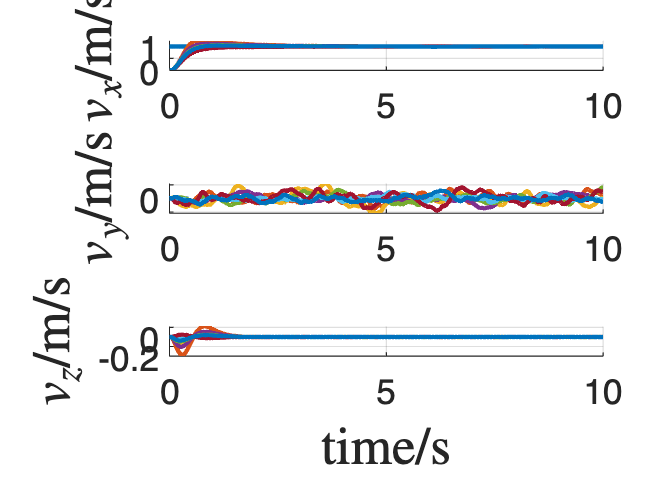



% Figure 3: real time velocity tracking histories
figure('Position',[1020 510 510 365]);
axes('NextPlot','replacechildren', 'ColorOrder',C);
subplot(3,1,1)
hold on
plot(tArray,net.formations(k).quadrotors(1).leaderStateHistory(:,4)','--',LineWidth=2);
for k = 1:1:numOfFormations
    for i = 2:1:numOfQuadrotors(k)
        plot(tArray,net.formations(k).quadrotors(i).followerStateHistory(:,4)','-',LineWidth=2);
    end
end
set(gca,fontsize=16);
ylabel('$v_x$/m/s','Interpreter','latex',fontsize=24)
grid on 

subplot(3,1,2)
hold on
plot(tArray,net.formations(k).quadrotors(1).leaderStateHistory(:,5)','--',LineWidth=2);
for k = 1:1:numOfFormations
    for i = 2:1:numOfQuadrotors(k)
        plot(tArray,net.formations(k).quadrotors(i).followerStateHistory(:,5)','-',LineWidth=2);
    end
end
set(gca,fontsize=16);
ylabel('$v_y$/m/s','Interpreter','latex',fontsize=24)
grid on 

subplot(3,1,3)
hold on
plot(tArray,net.formations(k).quadrotors(1).leaderStateHistory(:,6)','--',LineWidth=2);
for k = 1:1:numOfFormations
    for i = 2:1:numOfQuadrotors(k)
        plot(tArray,net.formations(k).quadrotors(i).followerStateHistory(:,6)','-',LineWidth=2);
    end
end
set(gca,fontsize=16);
ylabel('$v_z$/m/s','Interpreter','latex',fontsize=24)
xlabel('time/s','Interpreter','latex',fontsize=24)
% legend(Location="eastoutside")
% xlim([0 10]);
% ylim([-5 45]);
grid on 

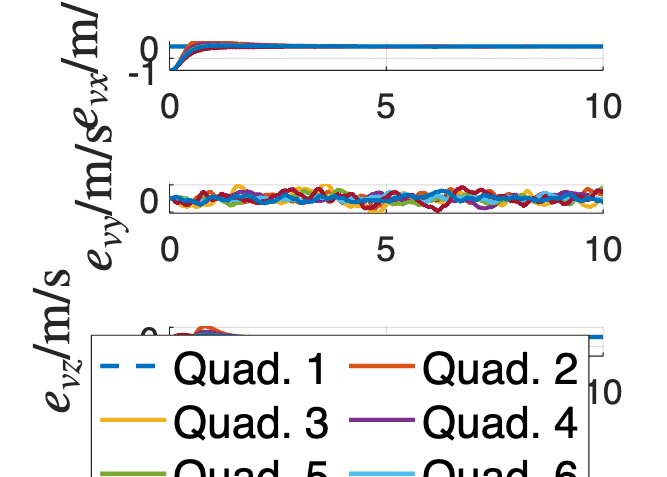



% Figure 4: real time velocity tracking errors histories
figure('Position',[0 0 510 365]);
axes('NextPlot','replacechildren', 'ColorOrder',C);
subplot(3,1,1)
hold on
plot(tArray,zeros(1,timeLength),'--',LineWidth=2,DisplayName=['Quad. ',num2str(1)]);
for k = 1:1:numOfFormations
    for i = 2:1:numOfQuadrotors(k)
        plot(tArray,net.formations(k).quadrotors(i).errorHistory(:,4)','-',LineWidth=2,DisplayName=['Quad. ',num2str(i)]);
    end
end
set(gca,fontsize=16);
ylabel('$e_{vx}$/m/s','Interpreter','latex',fontsize=24)
grid on 

subplot(3,1,2)
hold on
plot(tArray,zeros(1,timeLength),'--',LineWidth=2,DisplayName=['Quad. ',num2str(1)]);
for k = 1:1:numOfFormations
    for i = 2:1:numOfQuadrotors(k)
        plot(tArray,net.formations(k).quadrotors(i).errorHistory(:,5)','-',LineWidth=2,DisplayName=['Quad. ',num2str(i)]);
    end
end
set(gca,fontsize=16);
ylabel('$e_{vy}$/m/s','Interpreter','latex',fontsize=24)
grid on 

subplot(3,1,3)
hold on
plot(tArray,zeros(1,timeLength),'--',LineWidth=2,DisplayName=['Quad. ',num2str(1)]);
for k = 1:1:numOfFormations
    for i = 2:1:numOfQuadrotors(k)
        plot(tArray,net.formations(k).quadrotors(i).errorHistory(:,6)','-',LineWidth=2,DisplayName=['Quad. ',num2str(i)]);
    end
end
set(gca,fontsize=16);
ylabel('$e_{vz}$/m/s','Interpreter','latex',fontsize=24)
xlabel('time/s','Interpreter','latex',fontsize=24)
legend(Location="northeast",FontSize=20,NumColumns=2,Orientation="horizontal")
% xlim([0 10]);
% ylim([-1.5 2]);
grid on 

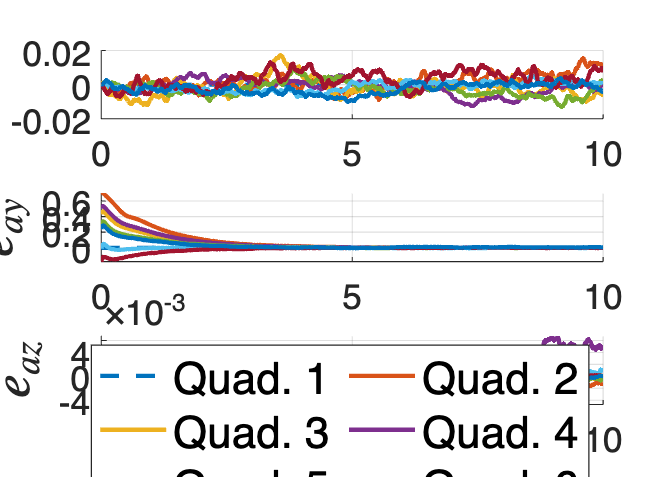


% Figure 5: real time orientation tracking errors histories
figure('Position',[510 0 510 365]);
axes('NextPlot','replacechildren', 'ColorOrder',C);
subplot(3,1,1)
hold on
plot(tArray,zeros(1,timeLength),'--',LineWidth=2,DisplayName=['Quad. ',num2str(1)]);
for k = 1:1:numOfFormations
    for i = 2:1:numOfQuadrotors(k)
        plot(tArray,net.formations(k).quadrotors(i).errorHistory(:,7)','-',LineWidth=2,DisplayName=['Quad. ',num2str(i)]);
    end
end
set(gca,fontsize=16);
ylabel('$e_{ax}$','Interpreter','latex',fontsize=24)
grid on 

subplot(3,1,2)
hold on
plot(tArray,zeros(1,timeLength),'--',LineWidth=2,DisplayName=['Quad. ',num2str(1)]);
for k = 1:1:numOfFormations
    for i = 2:1:numOfQuadrotors(k)
        plot(tArray,net.formations(k).quadrotors(i).errorHistory(:,8)','-',LineWidth=2,DisplayName=['Quad. ',num2str(i)]);
    end
end
set(gca,fontsize=16);
ylabel('$e_{ay}$','Interpreter','latex',fontsize=24)
grid on 

subplot(3,1,3)
hold on
plot(tArray,zeros(1,timeLength),'--',LineWidth=2,DisplayName=['Quad. ',num2str(1)]);
for k = 1:1:numOfFormations
    for i = 2:1:numOfQuadrotors(k)
        plot(tArray,net.formations(k).quadrotors(i).errorHistory(:,9)','-',LineWidth=2,DisplayName=['Quad. ',num2str(i)]);
    end
end
set(gca,fontsize=16);
ylabel('$e_{az}$','Interpreter','latex',fontsize=24)
xlabel('time/s','Interpreter','latex',fontsize=24)
legend(Location="northeast",FontSize=20,NumColumns=2,Orientation="horizontal")
% xlim([0 10]);
% ylim([-1.5 2]);
grid on 

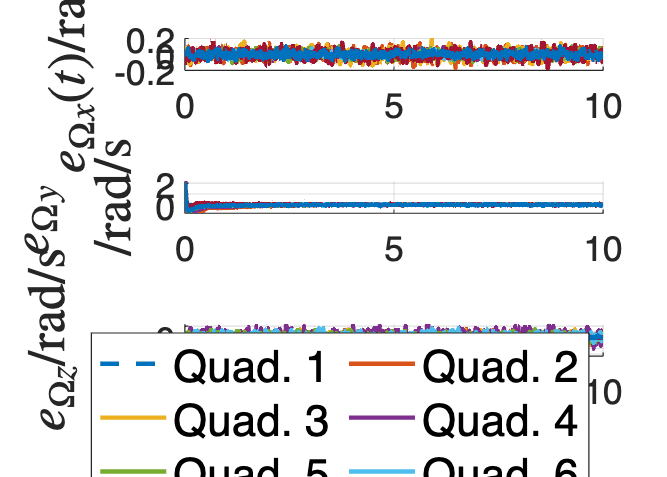



% Figure 6: real time angular velocity tracking errors histories
figure('Position',[1020 0 510 365]);
axes('NextPlot','replacechildren', 'ColorOrder',C);
subplot(3,1,1)
hold on
plot(tArray,zeros(1,timeLength),'--',LineWidth=2,DisplayName=['Quad. ',num2str(1)]);
for k = 1:1:numOfFormations
    for i = 2:1:numOfQuadrotors(k)
        plot(tArray,net.formations(k).quadrotors(i).errorHistory(:,10)','-',LineWidth=2,DisplayName=['Quad. ',num2str(i)]);
    end
end
set(gca,fontsize=16);
ylabel('$e_{\Omega x}(t)$/rad/s','Interpreter','latex',fontsize=24)
grid on 

subplot(3,1,2)
hold on
plot(tArray,zeros(1,timeLength),'--',LineWidth=2,DisplayName=['Quad. ',num2str(1)]);
for k = 1:1:numOfFormations
    for i = 2:1:numOfQuadrotors(k)
        plot(tArray,net.formations(k).quadrotors(i).errorHistory(:,11)','-',LineWidth=2,DisplayName=['Quad. ',num2str(i)]);
    end
end
set(gca,fontsize=16);
ylabel('$$e_{\Omega y}$/rad/s','Interpreter','latex',fontsize=24)
grid on 

subplot(3,1,3)
hold on
plot(tArray,zeros(1,timeLength),'--',LineWidth=2,DisplayName=['Quad. ',num2str(1)]);
for k = 1:1:numOfFormations
    for i = 2:1:numOfQuadrotors(k)
        plot(tArray,net.formations(k).quadrotors(i).errorHistory(:,12)','-',LineWidth=2,DisplayName=['Quad. ',num2str(i)]);
    end
end
set(gca,fontsize=16);
ylabel('$e_{\Omega z}$/rad/s','Interpreter','latex',fontsize=24)
xlabel('time/s','Interpreter','latex',fontsize=24)
legend(Location="northeast",FontSize=20,NumColumns=2,Orientation="horizontal")
% xlim([0 10]);
% ylim([-1.5 2]);
grid on 